# BCN Analisis electrolinera

clc
clearvars
close all

Script for importing data from the following text file:

Auto-generated by MATLAB on 22-Mar-2022 10:33:45

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 18);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["ID", "CHARGINGPOINT", "CONNECTOR", "STARTTIME", "STOPTIME", "DURATIONmin", "CONSUMPTIONkWh", "VEHICLE", "MODEL", "Charger", "AvPower", "Day", "ora", "Mins", "mese", "BatteriaEkWh", "FractSOC", "Pmax"];
opts.VariableTypes = ["double", "categorical", "categorical", "datetime", "datetime", "double", "double", "categorical", "categorical", "categorical", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["CHARGINGPOINT", "CONNECTOR", "VEHICLE", "MODEL", "Charger"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "STARTTIME", "InputFormat", "dd/MM/yyyy");
opts = setvaropts(opts, "STOPTIME", "InputFormat", "dd/MM/yyyy");

% Import the data
data = readtable("C:\Users\jyeregui\Dropbox (MGEP)\Josu\2. BrainEN\BrainEN-Electrolinera\Load Profile Generator\BCN\Charge2019_EV_AMB.csv", opts)

data = 36413×18 table
    ID                                    CHARGINGPOINT                                         CONNECTOR         STARTTIME      STOPTIME     DURATIONmin    CONSUMPTIONkWh      VEHICLE          MODEL         Charger    AvPower    Day    ora    Mins    mese    BatteriaEkWh    FractSOC    Pmax
    __    ______________________________________________________________________________    __________________    __________    __________    ___________    ______________    ___________    ______________    _______

clear opts

### Procesar tabla

% 
[~, data.StartWeek] = weekday(data.STARTTIME);
data.StartWeek = cellstr(data.StartWeek);
data = convertvars(data, {'StartWeek', 'Charger', 'CHARGINGPOINT'}, 'categorical');

data.Arrival = data.ora * 60 + data.Mins;
data.Departure = data.Arrival + data.DURATIONmin;

### Histogramas electrolineras 1 Día

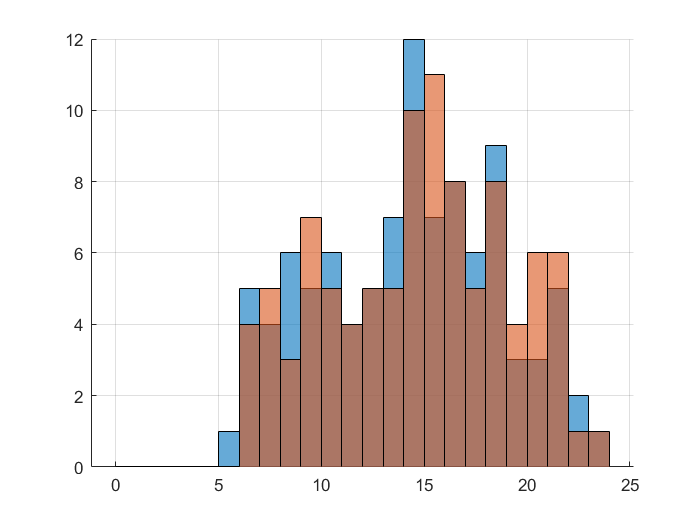

day = 75;
pos_days = unique(data.STARTTIME);
data_day = data(data.STARTTIME == pos_days(day), ["Arrival", "Departure"]);

figure
hold on
grid on
histogram(data_day.Arrival/60, 0:24)
histogram(data_day.Departure/60, 0:24)